### Driving towards april tag behaviors

clear all



% Connect to raspi
%     robotPi = raspi('192.168.34.15', 'pi', 'raspberry');
    robotPi = raspi('192.168.33.177', 'pi', 'raspberry');

    roverServos = I2C_Servo_pHAT(robotPi);

% Create connection to the V2 Pi Camera
    robotCam = cameraboard(robotPi, 'Resolution', '1280x720');   
    robotCam.ExposureMode = 'night';
    robotCam.AWBMode = 'fluorescent';

% Set up servos, PiCam, and QWIIC analog input
[adcDevice1, adcDevice2] = QWIICInputSetup(robotPi)

adcDevice1 =   ads1015 with properties:

             Address: 72
       OperatingMode: 'continuous'
        VoltageScale: 4.096000000000000
    SamplesPerSecond: 3300


adcDevice2 =   ads1015 with properties:

             Address: 73
       OperatingMode: 'continuous'
        VoltageScale: 4.096000000000000
    SamplesPerSecond: 3300


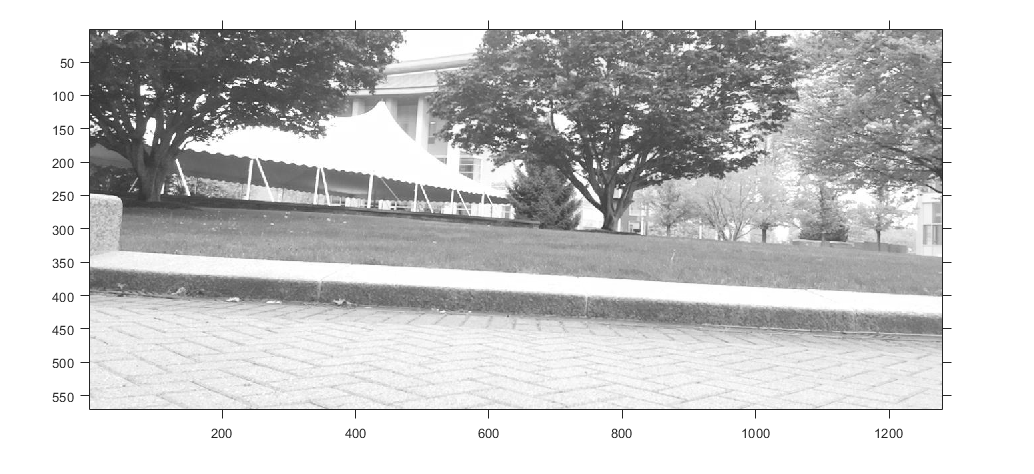

    img = snapshotCustom(robotCam);
    img = rgb2gray(img);
    cropped_img = img(150:end,:);
    edge_img = edge(cropped_img,"Canny",.06);
    
    imshow(cropped_img)

    bw_image = bwareaopen(edge_img, 10);
        
    [H,T,R] = hough(bw_image);
%     imshow(H,[],'XData',T,'YData',R,...
%                 'InitialMagnification','fit');
%     xlabel('\theta'), ylabel('\rho');
    axis on, axis normal, hold on;

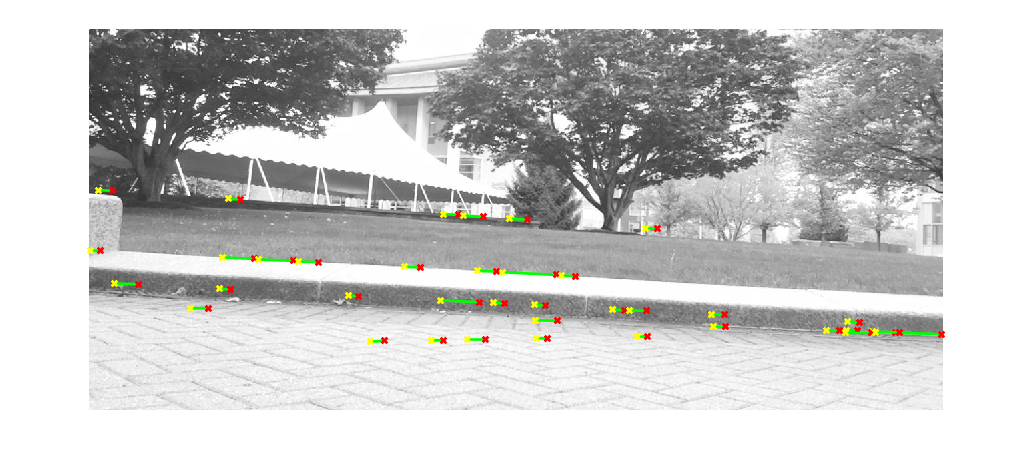

    
    P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
    x = T(P(:,2)); y = R(P(:,1));
%     plot(x,y,'s','color','white');
    
    lines = houghlines(bw_image,T,R,P,'FillGap',5,'MinLength',7);
    figure, imshow(cropped_img), hold on
%     figure(figureLineDetection);                            
%     imshow()
    max_len = 0;
    threshold_length = 15;
    for k = 1:length(lines)
       xy = [lines(k).point1; lines(k).point2];   
       % Determine the endpoints of the longest line segment
       len = norm(lines(k).point1 - lines(k).point2);
       slope(k) = 0;
       if ( len > threshold_length)
%            Plot beginnings and ends of lines
           plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green'); 
           plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
           plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
           slope(k) = (xy(2,2) - xy(1,2))/(xy(1,1) - xy(2,1));
       end     
    end

    
    slope_final = mean(slope)

slope_final = -0.0115

    % 0.02 for neutral
    % 0.03 for positive
    %0.0042 for negative

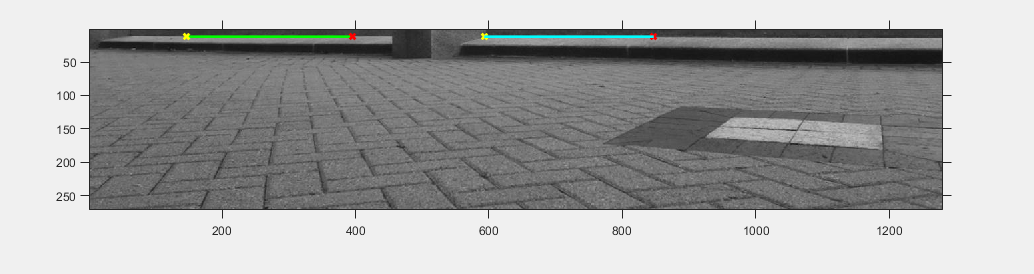

slope = 0

max_slope = 0

figureLineDetection = figure('name', 'figureLineDetection', 'NumberTitle', 'off', 'Visible', 'on');

[slope, max_slope]= find_slope_lines(robotCam,figureLineDetection)

[rawRangeData] = SharpIRRange(adcDevice1, adcDevice2);
rawRangeData'

ans =    0.899277443769646
   0.449763725699637
   0.353385784478286
   0.641519577623829
   0.995905392620624


figureLineDetection = figure('name', 'figureLineDetection', 'NumberTitle', 'off', 'Visible', 'on');
format long
    while 1
   
    [slope, max_slope]= find_slope_lines(robotCam,figureLineDetection);

    slope = max_slope
    % Rover drive speed
    speed = 43;
 
        % Drive towards april tag % negative slope means turn right
        if slope < -0.01
            % Steer to right
            disp("steering right")
            bearing = 2.5;  %degrees
            DriveRover(robotPi,roverServos,bearing, speed);

        else
            % Steer to left % large slope turn left
            disp("steering left")
            bearing = -3;   %degrees
            DriveRover(robotPi,roverServos,bearing, speed);
        end
        
        [rawRangeData] = SharpIRRange(adcDevice1, adcDevice2)
        threshold = 1;
        % left sensors
        if rawRangeData(1)>threshold || rawRangeData(2)>threshold
            disp("steering hard right bc of obstacles")
            bearing = 8;  %degrees
        end
        
        %v right sensors
        if rawRangeData(4)>threshold || rawRangeData(5)>threshold
            disp("steering hard left bc of obstacles")
            bearing = -8;  %degrees
        end            
        
        pause(3)
        DriveRover(robotPi,roverServos,bearing, 0);
    end

slope =   -0.050000000000000


steering right


rawRangeData =    0.448013672292245   0.642519608142338   0.867401470992157   0.003000091555528   0.803149510177923


slope =   -0.045454545454545


steering right


rawRangeData =    0.802524491103854   0.642144596697897                   0   0.737897518845180   0.867401470992157


slope =    0.202380952380952


steering left


rawRangeData =    0.642519608142338   0.289133823664052   0.707021576586199   0.481889706106754   0.803024506363109


slope =   -0.060975609756098


steering right


rawRangeData =    0.803149510177923   0.449763725699637   0.610393627735221   0.706896572771386   0.931653431806391


slope =   -0.169491525423729


steering right


rawRangeData =                    0   0.353385784478286   0.674645588549455                   0   0.771023529770806


slope =   -0.326086956521739


steering right


rawRangeData =    0.610393627735221   0.321259804071169   0.642644611957152   0.481889706106754                   0


slope =      0


steering left


rawRangeData =    0.353385784478286   0.224756859035005                   0   0.674645588549455   1.028031373027741


steering hard left bc of obstacles


slope =    9.571428571428571


steering left


rawRangeData =    0.737397503585925                   0   0.867776482436598                   0   0.963779412213507


slope =    6.218750000000000


steering left


rawRangeData =                    0   0.449763725699637                   0   0.512015625476852   0.963779412213507


function [rawRangeData] =  SharpIRRange(adcDevice1, adcDevice2)
     rawRangeData1 = SENSE_ADC(adcDevice1);
     rawRangeData2 = SENSE_ADC(adcDevice2);
     rawRangeData = [rawRangeData2(1:3),rawRangeData1(1:2)];
end


ACT

function pwm = AngleForServo(angle)
pwm = ((angle + 85.21)/1.755) - 2.35;
pwm = pwm(1);
end

function [] = DriveRover(robotPi,roverServos,direction,speed)
    roverServos.setServoPWM(1,AngleForServo(direction));    % commands steering servo
    roverServos.setServoPWM(2,speed);    % commands drive speed controller
end

line detection

function [slope_final, max_slope] = find_slope_lines(robotCam, figureLineDetection)
    img = snapshotCustom(robotCam);
    img = rgb2gray(img);
    cropped_img = img(415:end,:);

    edge_img = edge(cropped_img,"Canny",.06);
    
    threshold_length = 200;

    bw_image = bwareaopen(edge_img, threshold_length);

    imshow(cropped_img)

        
    [H,T,R] = hough(bw_image);
    axis on, axis normal, hold on;
    
    P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
%     x = T(P(:,2)); y = R(P(:,1));
%     plot(x,y,'s','color','white');
    
    lines = houghlines(bw_image,T,R,P,'FillGap',5,'MinLength',7);
%     figure, imshow(cropped_img), hold on

    max_len = 0;
    max_slope = 0;
    for k = 1:length(lines)
       xy = [lines(k).point1; lines(k).point2];   
       % Determine the endpoints of the longest line segment
       len = norm(lines(k).point1 - lines(k).point2);
       slope(k) = 0;
       
       if ( len > threshold_length)
%            Plot beginnings and ends of lines
           plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green'); 
           plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
           plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
           slope(k) = (xy(2,2) - xy(1,2))/(xy(1,1) - xy(2,1));
       end  
       
       if ( len > max_len && abs(slope(k)) < 0.2)
          max_len = len;
          xy_long = xy;
          max_slope = (xy(2,2) - xy(1,2))/(xy(1,1) - xy(2,1));
       end
       
       figure(figureLineDetection);                            
%        imshow(cropped_img)
       
    end
    plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','cyan');

    slope_final = mean(slope);
end

function [adcDevice1, adcDevice2] = QWIICInputSetup(robotPi)
% create two SparkFun Qwiic Analog Input adc device that are present on i2c
% bus 1 at address 0x48 and at adress 0x49

adcDevice1 = ads1015(robotPi,'i2c-1','0x48'); % 2 sonar sensor and 2 IR
adcDevice2 = ads1015(robotPi,'i2c-1','0x49'); % 3 IR sensors
end

function rawRangeDataN = SENSE_ADC(adcDeviceN)
     % read ADC1 Pin 0-4 voltage
    rawRangeDataN = [adcDeviceN.readVoltage(0), adcDeviceN.readVoltage(1), ...
                adcDeviceN.readVoltage(2), adcDeviceN.readVoltage(3)]; 
end

